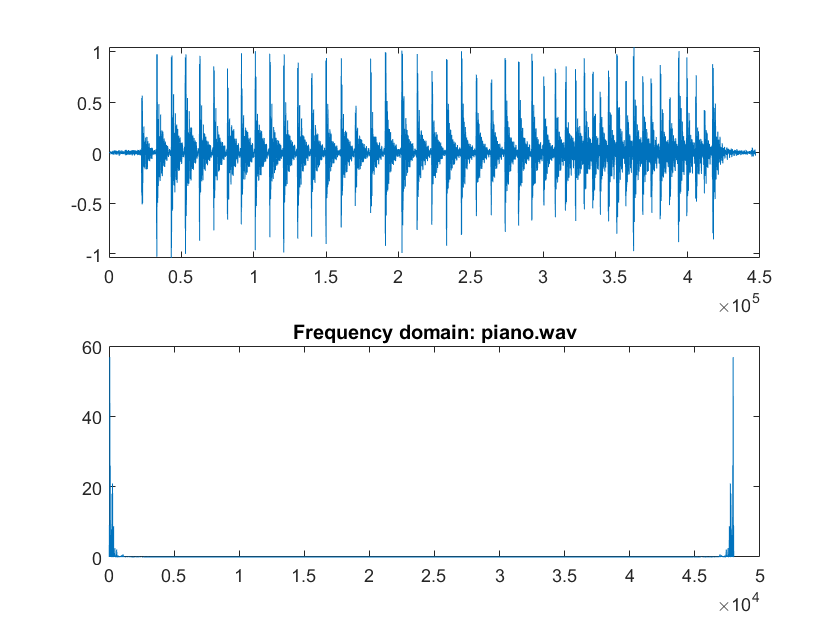

clc
clear
[x,fs]=audioread('M.wav');
sound(x,fs);
subplot(2,1,1);
plot(x);
xlen=length(x);


c = fft(x);
n = length(x);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
a = abs(c).^2/n;    % power of the DFT
subplot(2,1,2);
plot(f,a);
title('Frequency domain: piano.wav');

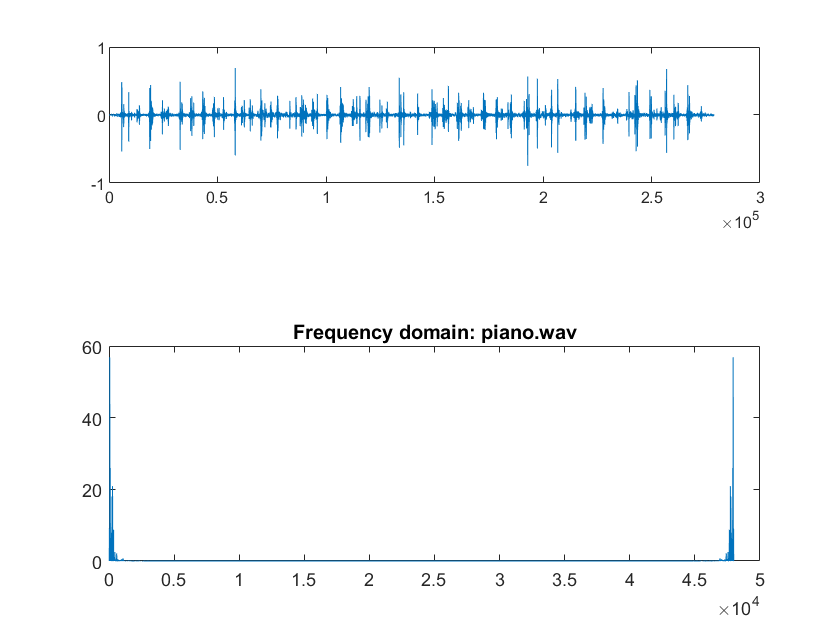




[y,fe]=audioread('N.wav');
sound(y,fs);
subplot(3,1,1);
plot(y);

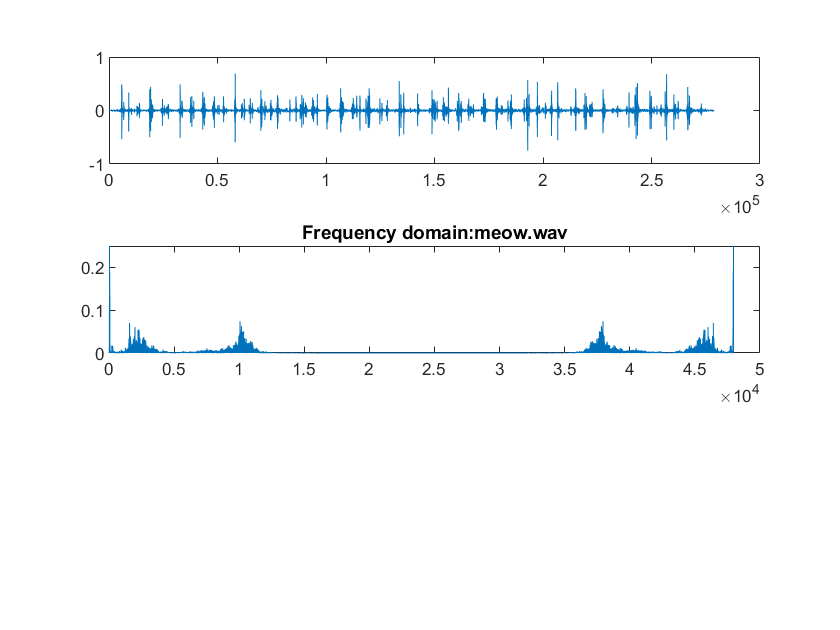

xlen=length(y);


g = fft(y);
n = length(y);          % number of samples
f = (0:n-1)*(fe/n);     % frequency range
b = abs(g).^2/n;    % power of the DFT
subplot(3,1,2);
plot(f,b);
title('Frequency domain:meow.wav');

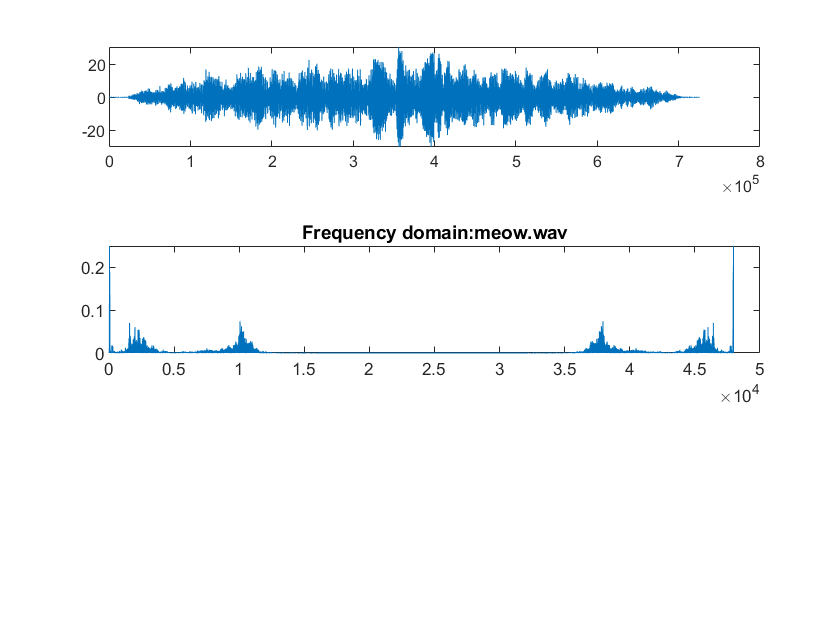



out=conv2(x,y);
sound(out);

subplot(4,1 ,1);
plot(out);